# Control and Instrumentation Lab Assignment 4

**SWARNENDU PAUL 19EE3FP18**

**Q7.**

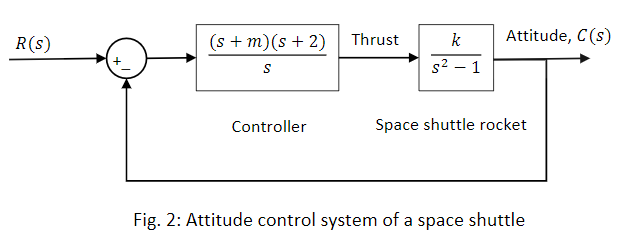

We have to find the range of k and m, so that the Altitude control system is stable.

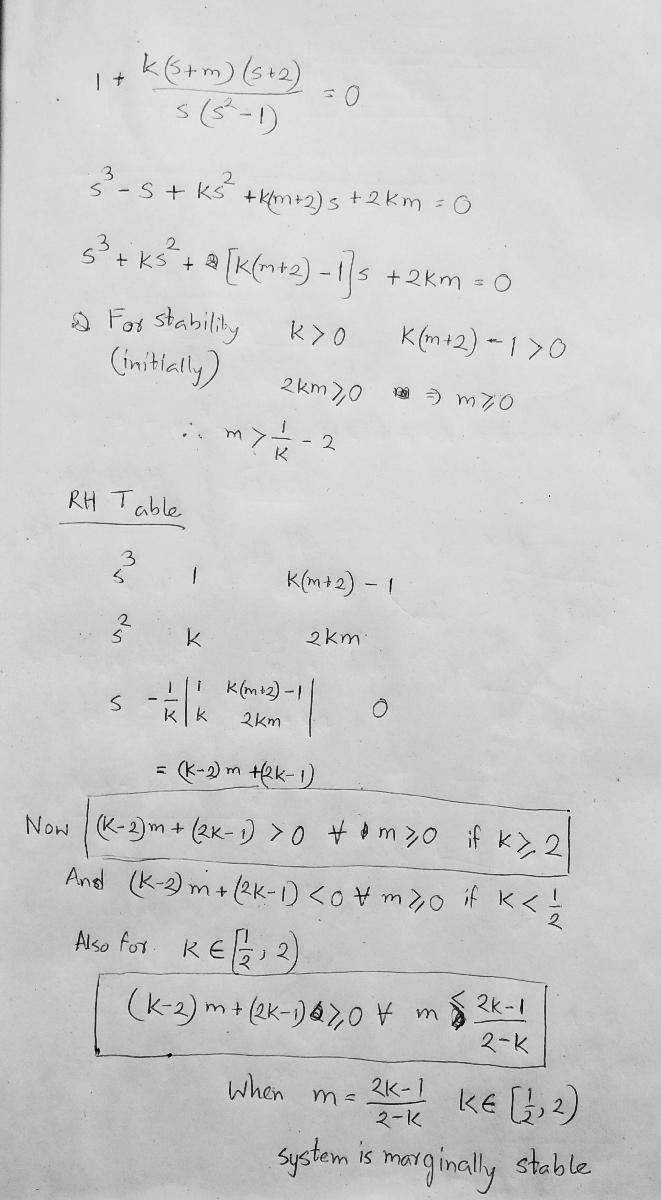

So the given closed-loop system is stable when 


$$k\geq2, m\geq0$$


or


$$\frac{1}{2}\leq k<2,0\leq m\leq \frac{2k-1}{2-k}$$
 

When $k\geq 2$ m can take any value between $(0,\infty)$. But to find the stability region using rhc function we have taken both the range of k and m upto 20.

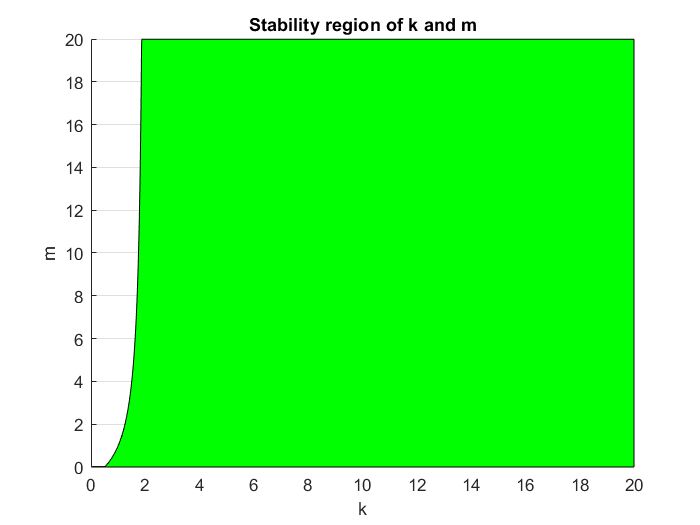

k=0.01:0.01:20;
m=0:0.01:20;
y=zeros(size(k));
for i=1:length(k)
    for j=1:length(m)-1
        a=rhc([1,k(i),k(i)*(m(j)+2)-1,2*k(i)*m(j)],0);
        b=rhc([1,k(i),k(i)*(m(j+1)+2)-1,2*k(i)*m(j+1)],0);
        if(a~=b)||(b==1 && j==length(m)-1)
            y(i)=m(j);
        end
    end
end
figure;
patch([k,fliplr(k)],[y,zeros(size(y))],'g')
xlabel("k");
ylabel("m");
title("Stability region of k and m");
grid on

Now we need to find the range of k and m, for which steady state error of the system for ramp input is less than or equal to 10% of input magnitude.

Let $G_1(s)=\frac{(s+m)(s+2)}{s}$ and $G_2(s)=\frac{k}{s^2-1}$ . Then steady state error for ramp response for the given system is,

$e_{ss}=\frac{1}{\lim_{s \to 0}sG_1(s)G_2(s)}$ when the system is stable.

which is equal to $-\frac{1}{2km}$ .

Now this value is between $\pm 0.1$(10%), now as both k and m is positive so,

$-\frac{1}{2km} \geq -0.1$ so $m\geq \frac{5}{k}$ 

Stability region:

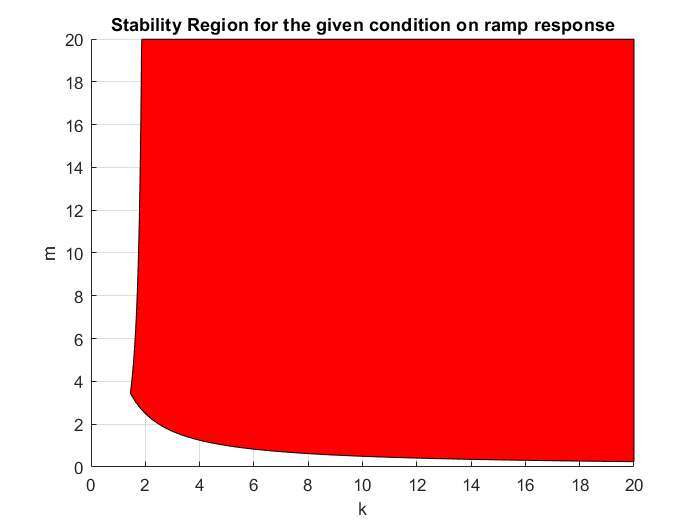

y1=5./k;
Li=(y>=y1);
figure;
patch([k(Li),fliplr(k(Li))],[y(Li),fliplr(y1(Li))],'r');
xlabel("k");
ylabel("m");
grid on
title("Stability Region for the given condition on ramp response");

**Q8.**

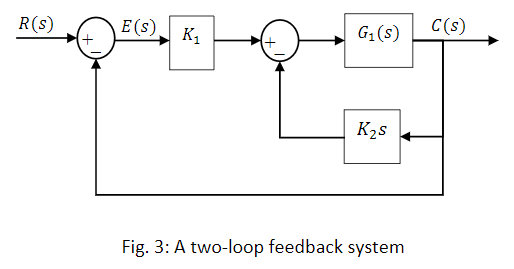

Here $G_1(s)=\frac{1}{s(s+2)(s+4)}$

**a,b.** We have to find $K_2$ so that the inner loop has 2 equal negative poles.

So $1+K_2sG_1(s)=0$ will have 2 equal -ve roots.

Characteristic equation

$(s+2)(s+4)+K_2=0$ For $K_2=1$ the equation becomes

$s^2+6s+9=0$ which has 2 equal roots -3,-3

Now the given block diagram can be reduced by combining $G_1(s)$ and $K_2s$,


$$G(s)=\frac{1}{s(s+2)(s+4)+s}$$
 

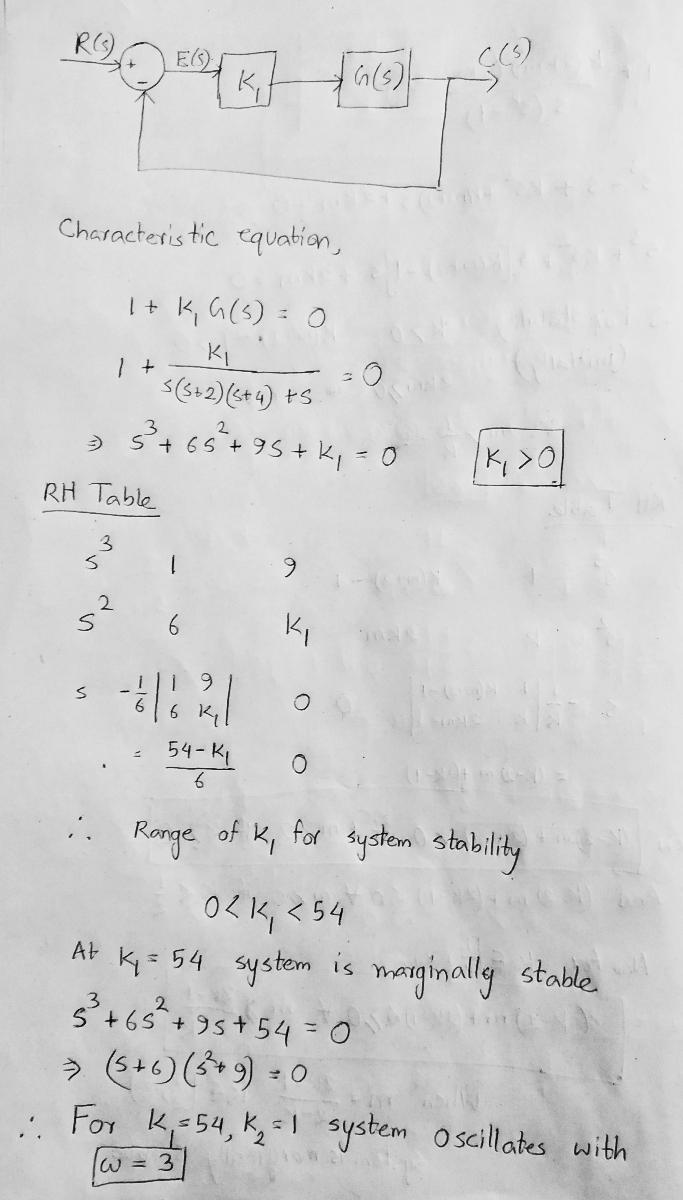

Hence, for given value of $K_2=1$ we get the corresponding range of $K_1 \in (0,54)$

At $K_1=54$ the system is marginally stable i.e. oscillates. Frequency of Oscillation will be 3rad/sec

If value of $K_2$ is not specified, the system oscillates with frequency $\sqrt{8+K_2}$ rad/sec when $K_1=6(8+K_2)$ 

We can confirm the result using the rhc function.

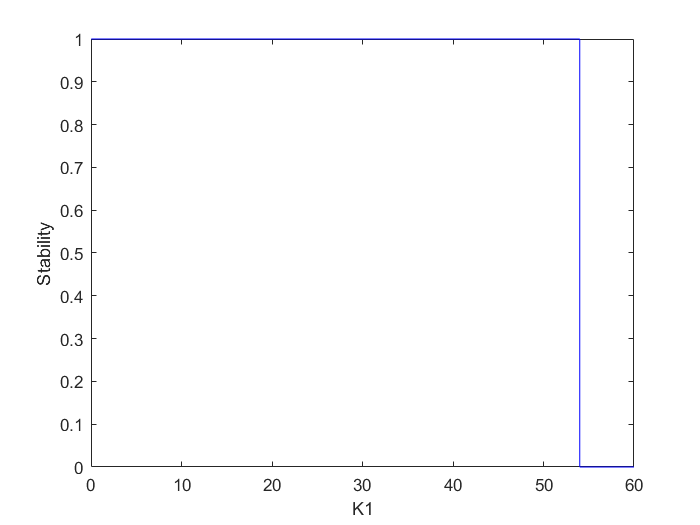

k1=1e-2:1e-2:60;
y=zeros(size(k));
for i =1:length(k1)
    y(i)=rhc([1,6,9,k1(i)],0);
end
figure;
plot(k1,y,"b-")
xlabel("K1");
ylabel("Stability");

System becomes unstable when $K_1>54$

**c.**

As a closed-loop pole at $s=5$ will make the system unstable, we won't be able to approximate the step response as underdamped.

Characteristic equation of the system,


$$s^3+6s^2+(8+K_2)s+K_1=0$$


if $s=5$ is a pole then,

solving we get, $K_1=-5(63+K_2)$ 

As the above result does not have any significance with the 2nd part of question, lets assume the pole was meant to be at $s=-5$

Then solving we get,


$$K_1=5(K_2+3)$$


Factorising the characteristic equation we get,


$$(s+5)(s^2+s+K_2+3)=0$$


So while one pole is at $s=-5$, both the complex poles have real value = $-\frac{1}{2}$ so real pole is 10 times far from the imaginary axis w.r.t. the imaginary poles.

So we can apply **Dominant pole approximation** here and reduce the step response of the system to an underdamped second order response.

Lets take an example.

$K_2=1$ so, $K_1=20$ 

Calculating the transfer function for the system we get,


$$G(s)=\frac{20}{s^3+6s^2+9s+20}$$


Using **dominant pole approximation**,


$$G_{app}(s)=\frac{4}{s^2+s+4}$$


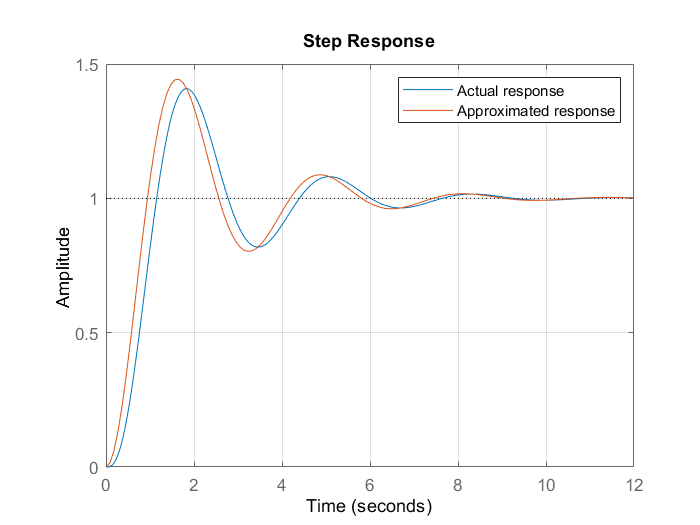

tf1=tf(20,[1,6,9,20]);
tf2=tf(4,[1,1,4]);
step(tf1,tf2);
legend("Actual response","Approximated response")
grid on

Clearly, we can apply dominant pole approximation in this case.